# Curva de Respuesta a la Dosis Ajustada

Este es un ejemplo de cómo MATLAB puede ser utilizado para facilitar un flujo de trabajo típico para un experimentalista que necesita automatizar el análisis a través de muchos (cientos) de experimentos con datos de instrumentos organizados en archivos TXT, CSV o hojas de cálculo. En este ejemplo, queremos encontrar los principales candidatos de cientos de experimentos. Los datos están en archivos CSV de un Experimento de Dosis-Respuesta en un formato de placa microtituladora de 96 pocillos. Cada fila de datos corresponde a una dilución seriada (los 10 pocillos del medio) de un compuesto dado con un control negativo (primera columna) y un control positivo (última columna). Las lecturas de dosis-respuesta en cada micropozo están en unidades arbitrarias (por ejemplo, fluorescencia, luminiscencia, absorbancia) que varían de ~0 a ~100(%). Ajustamos los datos experimentales a un modelo de cuatro parámetros y añadimos una métrica de control de calidad extraída de la literatura científica. En el archivo *A_Microtiter_Plate_One* prototipamos nuestro flujo de trabajo. En este script estamos llamando a ese flujo de trabajo en un bucle. El resultado final es una tabla de compuestos ordenados en decreciente potencia y filtrados por una métrica de control de calidad. Esto también incluye un informe y un archivo de hoja de cálculo.

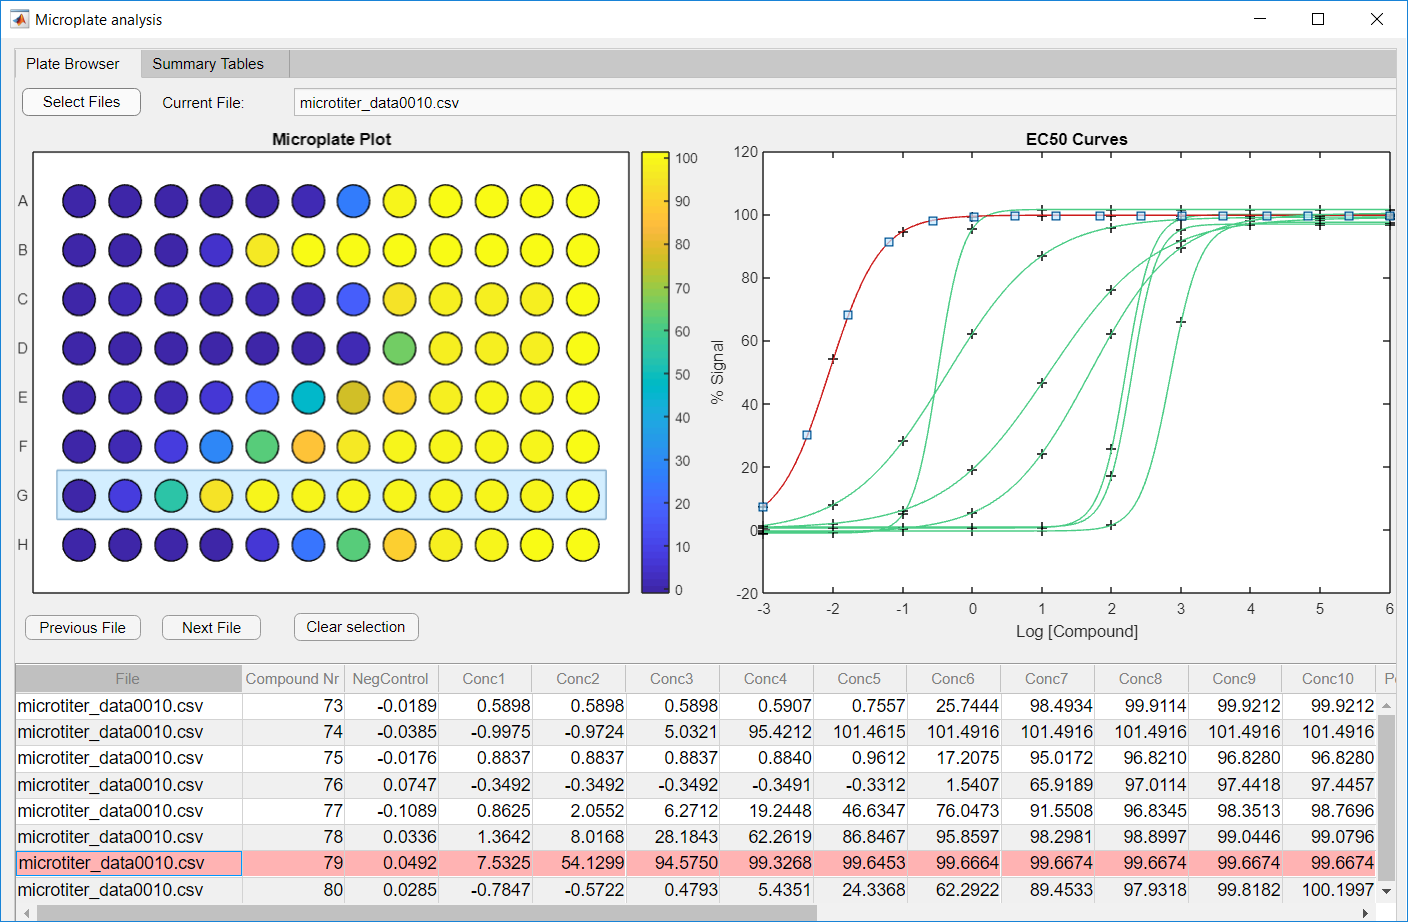

clear; close all; clc;

## Paso 1: Accede a los datos en MATLAB

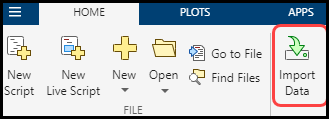

Utiliza la opción **Import Data** en la barra de herramientas.

data = readtable('data.csv')

data = 8×12 table
    NegControl     Conc1       Conc2      Conc3      Conc4       Conc5       Conc6       Conc7      Conc8     Conc9     Conc10    PosControl
    __________    ________    _______    _______    ________    ________    ________    ________    ______    ______    ______    __________

     -0.0937       0.33891      9.906     57.139      92.171      97.172      97.619      97.657     97.66     97.66     97.66      100.48  
     -0.0336       -0.5264    -0.5264    -0.5264     -0.5264     -0.5264    -0.52628    -0.47618    17.118    101.48    102.65      100.53  
     -0.0

## Paso 2:  Visualiza los datos

Para ello, utilizaremos una "Live Task"

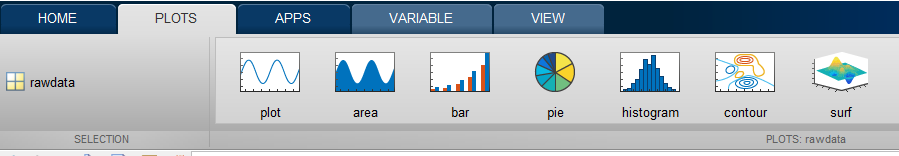

Let's try out a few of these visualizations and use the provided customization tools to adjust and automate custom data visualization

c = data.Variables

c =    -0.0937    0.3389    9.9060   57.1390   92.1710   97.1720   97.6190   97.6570   97.6600   97.6600   97.6600  100.4800
   -0.0336   -0.5264   -0.5264   -0.5264   -0.5264   -0.5264   -0.5263   -0.4762   17.1180  101.4800  102.6500  100.5300
   -0.0137   -0.4983    3.2407   53.9460   99.3890  102.3700  102.4800  102.4800  102.4800  102.4800  102.4800  101.8600
    0.0905    0.2136    0.2196    0.3525    3.2192   41.1440   94.8470  100.7800  101.0700  101.0800  101.0800  100.1200
   -0.0775   -0.7785    1.7212   27.3410   85.9810  100.9600  102.2200  102.3100  102.3200  102.3200  102.3200  101.7400
    0.0473   -0.0047    0.1516    1.9478   19.0260   73.4120   97.0630   99.8060  100.0500  100.0700  100.0700   99.7000
   -0.0149   -0.3653   -0.3653   -0.3653   -0.3653   -0.3545    9.0751  100.0300  101.0500  101.0500  101.0500   98.0900
   -0.0584    0.8869    0.8869    0.8870    0.9435   21.6330  101.4800  102.3300  102.3300  102.3300  102.3300  101.5600


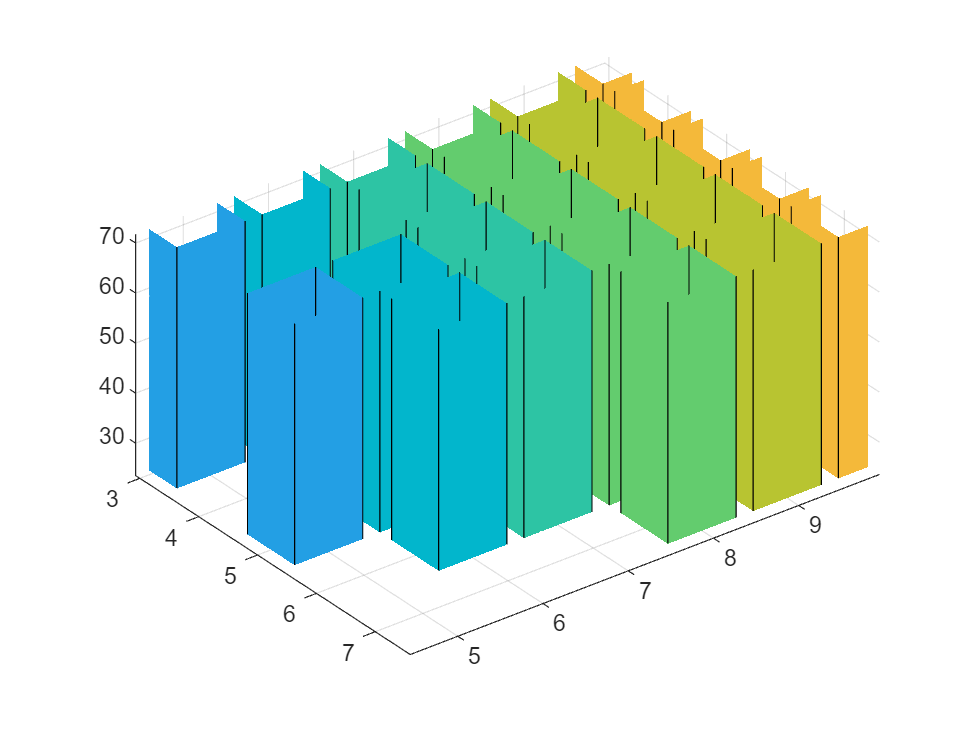

% Create bar3 of c
h2 = bar3(c);

bar3(data.Variables)

## Paso 3:  Preprocessar los datos

Los datos fueron importados a una **tabla**, uno de varios tipos de contenedores de datos. Las tablas están diseñadas para datos columnares o tabulares, por lo que acceder a los datos se puede hacer fácilmente por nombre o por números de fila y columna. La tabla también contiene metadatos accesibles a través de propiedades.

data.Properties

ans =   TableProperties with properties:
             Description: ''
                UserData: []
          DimensionNames: {'Row'  'Variables'}
           VariableNames: {'NegControl'  'Conc1'  'Conc2'  'Conc3'  'Conc4'  'Conc5'  'Conc6'  'Conc7'  'Conc8'  'Conc9'  'Conc10'  'PosControl'}
    VariableDescriptions: {}
           VariableUnits: {}
      VariableContinuity: []
                RowNames: {}
        CustomProperties: No custom properties are set.
      Use addprop and rmprop to modify CustomProperties.

Por ejemplo, asignemos nombres a las filas para etiquetar cada compuesto probado en la placa de microtitulación.

data.Properties.RowNames = cellstr("Compound"+(1:8))

data = 8×12 table
                 NegControl     Conc1       Conc2      Conc3      Conc4       Conc5       Conc6       Conc7      Conc8     Conc9     Conc10    PosControl
                 __________    ________    _______    _______    ________    ________    ________    ________    ______    ______    ______    __________
    Compound1     -0.0937       0.33891      9.906     57.139      92.171      97.172      97.619      97.657     97.66     97.66     97.66      100.48  
    Compound2     -0.0336       -0.5264    -0.5264    -0.5264     -0.5264     

Antes de poder ajustar los datos a nuestra ecuación, primero debemos aplicar las mediciones de control positivo y negativo. **¿Cómo se hace esto en Excel?**

data.Variables = data.Variables - mean(data.NegControl);
data.Variables = data.Variables ./ data.PosControl*100;
data

data = 8×12 table
    NegControl     Conc1       Conc2       Conc3       Conc4       Conc5       Conc6       Conc7     Conc8     Conc9     Conc10    PosControl
    __________    ________    ________    ________    ________    ________    ________    _______    ______    ______    ______    __________

     -0.07434      0.35612      9.8757      56.874      91.732      96.708      97.153     97.191    97.194    97.194    97.194       100    
    -0.014532     -0.50464    -0.50464    -0.50464    -0.50464    -0.50464    -0.50452    -0.4547    17.043    100.94    102.11       100    
    0

Una vez hecho esto, podemos eliminar las columnas de control positivo/negativo de nuestro conjunto de datos. Intenta hacerlo desde el Editor de Variables y copia y pega el código a continuación.

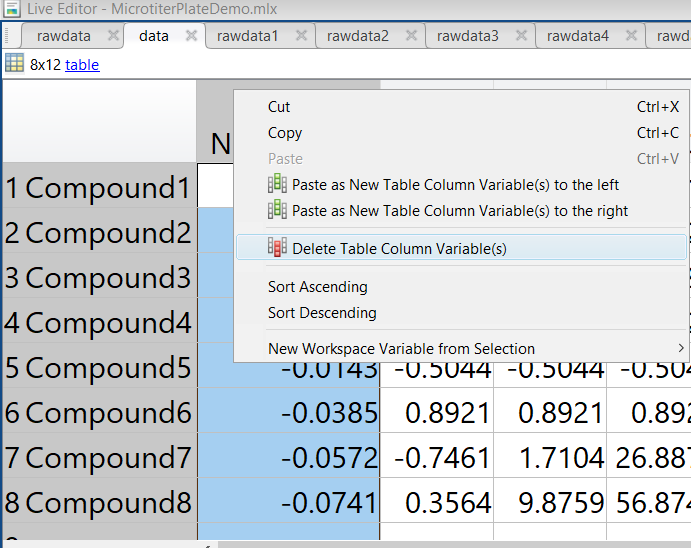

## Paso 4:  Analicemos los datos

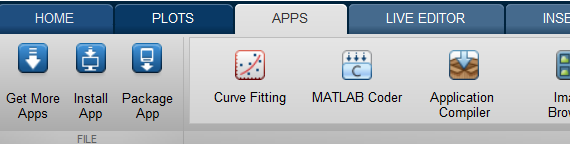

Las aplicaciones de MATLAB permiten un prototipado fácil y rápido mientras generan automáticamente el código para la automatización. Utiliza la aplicación de **Curve Fitter App** para ajustar cada compuesto a la siguiente ecuación:


$$R=\frac{\min -\max }{1+{\left(x/\mathrm{EC50}\right)}^{\mathrm{HillsSlope}} }+\max$$


donde:


$$\begin{array}{l}
1e-5\le \mathrm{EC50}\le 1\mathrm{e7}\\
0\le \mathrm{HillsSlope}\le 10\\
0\le \max \le 120\\
-20\le \min \le 5
\end{array}$$


y las concentraciones de entrada varían desde 1nM hasta 1M y las visualizamos como una curva sigmoidea:

conc = [0.001, 0.01, 0.1, 1, 10, 100, 1000, 10000, 100000, 1000000];
x = log10(conc)

x =     -3    -2    -1     0     1     2     3     4     5     6


Una vez que hayamos realizado el ajuste para un compuesto, podemos pedirle a la aplicación que genere el código MATLAB para poder repetir el proceso con el resto de los datos.

## Paso 5:  Automatizar el análisis de datos 

Para repetir el mismo proceso de análisis para todo el conjunto de datos, use un bucle **for**. Un bucle es un tipo de construcción de programación que permite controlar el flujo de un proceso. Las instrucciones de control de bucle permiten que una secuencia particular de comandos se repita cualquier número de veces. A continuación, el bucle **for** repite el proceso de ajuste para la tabla de datos completa.

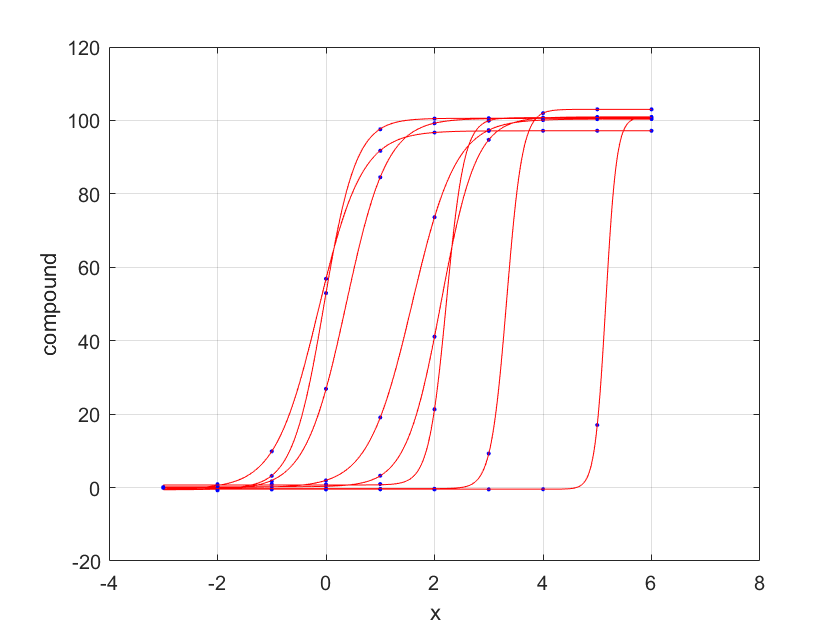

clf
h = height(data);
EC50resultsmtx = zeros(h,1);
for ii = 1:h
    compound = data{ii,1:10};
    [fitresult, gof] = createMicrotiterFit(x, compound);
    EC50resultsmtx(ii,:) = [fitresult.EC50];
end

EC50resultsmtx

EC50resultsmtx = 	1.0e+05 *

    0.0000
    1.4373
    0.0000
    0.0013
    0.0000
    0.0004
    0.0215
    0.0017


## Next Steps:  How do I generalize to multiple data files?

Introducing `datastore` for handling multiple data files from multiple locations across multiple formats.  `datastore` is a container datatype that points to where data lives and stores information about how it should be read in.

ds = datastore('Experimental_Data\*.csv');
ds.VariableNames = {'NegControl','Conc1','Conc2','Conc3','Conc4','Conc5','Conc6','Conc7','Conc8','Conc9','Conc10','PosControl'};
ds.ReadSize = 'file'

ds =   TabularTextDatastore with properties:

                      Files: {
                             ' ...\MicrotiterPlateFittingDemo\Experimental_Data\microtiter_data0001.csv';
                             ' ...\MicrotiterPlateFittingDemo\Experimental_Data\microtiter_data0002.csv';
                             ' ...\MicrotiterPlateFittingDemo\Experimental_Data\microtiter_data0003.csv'
                              ... and 27 more
                             }
               FileEncoding: 'UTF-8'
   AlternateFileSystemRoots: {}
          ReadVariableNames: false
              VariableNames: {'NegControl', 'Conc1', 'Conc2' ... and 9 more}
             DatetimeLocale: en_US

  Text Format Properties:
             NumHeaderLines: 0
                  Delimiter: ','
               RowDelimiter: '\r\n'
             TreatAsMissing: ''
               MissingValue: NaN

  Advanced Text Format 

Now we can perform the fitting on the preprocessed data.  Here we initialize an empty array (`results`) to capture the EC50's and operate on the datastore until there is no more data left to read.  

*NOTE:  within the `for` loop, MATLAB Code Analyzer has identified that the variable, `results`, is [increasing in size with every iteration](https://www.mathworks.com/help/releases/R2019a/matlab/matlab_prog/preallocating-arrays.html?container=jshelpbrowser).  This is not a recommended practice and should be avoided when possible.

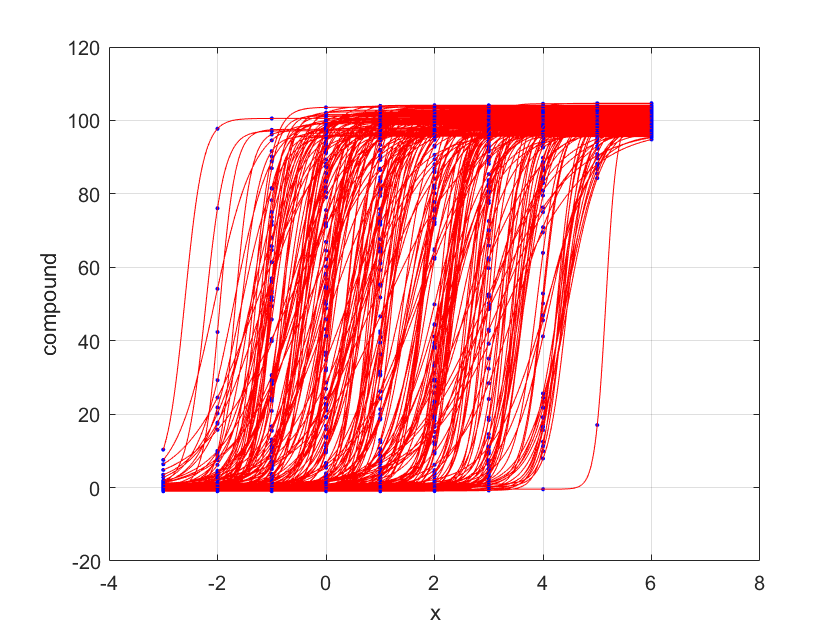

results = [];

while hasdata(ds)
    data = read(ds);
    
    data.Variables = data.Variables - mean(data.NegControl);
    data.Variables = data.Variables ./ data.PosControl*100;
    
    data = removevars(data, 'NegControl');
    data = removevars(data, 'PosControl');
    
    h = height(data);
    for ii = 1:h
        compound = data{ii,1:10};
        [fitresult, gof] = createMicrotiterFit(x, compound);
        results = [results;fitresult.EC50];
    end
end

writematrix(results,'myresults.csv')
reset(ds)

## Extension:  Alternatives for handling big data or scaling up

What if all the data needs to be processed at once? Is there any faster way of performing this analysis?  There are several alternatives to explore...

do = false;
 
if do
    edit BigDataAndTall.mlx
end